Fundamentos de control                                                                                                        

# Retardo de transporte

No todo es instantáneo

El **retardo de transporte**, también llamado **tiempo muerto**, aparece cuando existe un retardo temporal en un sistema entre un cambio en la entrada y su repercusión en la salida. Por ejemplo, si tenemos un sistema de calefacción basado en calentar agua que es distribuida a través de tuberías hasta una serie de radiadores, dado que el agua caliente ha de distribuirse por dichas tuberías, los radiadores no van a comenzar a calentarse hasta que no pase un determinado tiempo. En este caso, el tiempo transcurrido entre la activación de la calefacción y el comienzo en el aumento de la temperatura en el radiador es el denominado retardo de transporte. Nótese que este tiempo no se corresponde con la repuesta transitoria del sistema, o el tiempo que tarda la salida en alcanzar el valor deseado: durante el retardo de transporte no ocurre nada en la salida.

El retardo de transporte puede aparecer entre la entrada y el proceso, en la recepción de la salida, o en ambos casos, tal y como ilustra la siguiente imagen:

donde $u\left(t-\lambda_u \right)$ y $y\left(t-\lambda_y \right)$representa un retardo de $\lambda_u$ y $\lambda_y$ segundos, respectivamente. Estos retardos son típicos en en sistemas térmicos, hidráulicos y neumáticos, o incluso mecánicos. Otro ejemplo claro sería el de un robot espacial, donde las transmisiones introducen un retardo en la comunicación.

## 1. Modelando el retraso de transporte

El retraso de transporte, desde el punto de vista de la descripción externa de sistemas, puede modelarse empleando la propiedad de traslación en el tiempo de la transformada de Laplace:


$$L\left\lbrack u\left(t-\lambda_u \right)\right\rbrack =e^{-\lambda_u s} \;U\left(s\right)$$


El retardo de salida y de entrada pueden agruparse en un único retardo global, esto es $\lambda =\lambda_u +\lambda_y$. De este modo, la función de transferencia de un sistema con retardo resultaría:


$$\frac{Y\left(s\right)}{U\left(s\right)}=e^{-\lambda s} G\left(s\right)$$


En MATLAB podemos especificar que un sistema modelado mediante su función de transferencia tiene un retado bien a la entrada, a la salida, o agrupado empleando los siguientes parámetros de entrada en los comandos `tf` o `zpk`:

- `InputDelay`: especifica retardo en la entrada.

- `OuptutDelay`: especifica retardo en la salida.

- `IODelay`: especifica el retardo agrupado.

De manera similar puede definirse el retardo de un modelo representado mediante su espacio de estados, aunque esto no nos es de interés en este curso.

Simular este retraso con MATLAB resulta fácil. Si suponemos la función de transferencia $G(s)=e^{-\lambda s}\frac{1}{s+3}$ la cual incorpora un retardo de transporte de $\lambda$ segundos, el código MATLAB que la define:

lambda =0.7% Retardo ajustable de 1 a 10 segundos

lambda = 0.7000

G = tf(2,[1 3],'IODelay',lambda) % G es la función de transferencia con el retardo  

G =
 
                  2
  exp(-0.7*s) * -----
                s + 3
 
Continuous-time transfer function.
Model Properties


También se puede proceder definiendo la función de transferencia del retardo y operando aritméticamente, obteniendo el mismo resultado:

s = tf('s');
Gr = exp(-lambda*s);
Gp = tf(2,[1 3]);
G = Gr*Gp

G =
 
                  2
  exp(-0.7*s) * -----
                s + 3
 
Continuous-time transfer function.
Model Properties


**Tarea 1**: Supóngase el sistema de nivel de líquidos de la siguiente figura, donde la entrada al mismo es $q_i \left(t\right)$ (desviación de caudal de entrada, expresado en $m^3 /\textrm{seg}$)y la salida $h\left(t\right)$ (la altura del nivel de agua, expresada en $m$). 

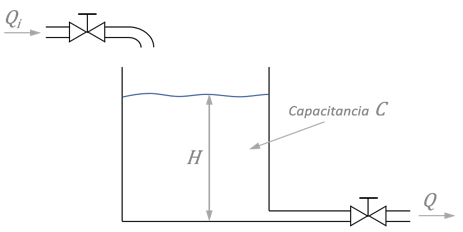

Este sistema se modela matemáticamente empleando la siguiente función de transferencia:


$$\frac{H\left(s\right)}{Q_i \left(s\right)}=\frac{R}{\textrm{RCs}+1}$$


Donde:

- $R$ es la resistencia para el flujo del líquido (cambio en la diferencia de nivel necesaria para producir un cambio de una unidad en el caudal),

- $C$es la capacitancia del tanque (cambio necesario en la cantidad de líquido almacenado para producir un cambio de una unidad en la altura).

Se pide simular

- Simular la respuesta del sistema ante una entrada escalón de amplitud 0.1, con $R=1\;\textrm{seg}/m^2$ y $C=2m^2$.

- Simular la respuesta del sistema con un modelado más realista, en el que se añade un retraso de transporte a la entrada de $2\;\textrm{seg}$ (tiempo que tarda el líquido en llegar desde que se abre la válvula de entrada hasta el tanque). Define este retraso de los dos modos comentados y comprueba que el resultado es el mismo (especificación del retardo en `tf` o `zpk`, u operando artiméticamente).

Mostrar ambas respuestas en la misma figura. 

% Tu código aquí
s = tf('s');
A = 0.1;
R = 1;
C = 2; 
G1 = ((R)/(R*C*s+1));                                                                                                    ;
step(0.1*G1);
hold on;
s = tf('s');
lambda = 2;
Gr = exp(-lambda*s);
Gp = ((R)/(R*C*s+1));
G = Gr*Gp

G =
 
                 1
  exp(-2*s) * -------
              2 s + 1
 
Continuous-time transfer function.
Model Properties


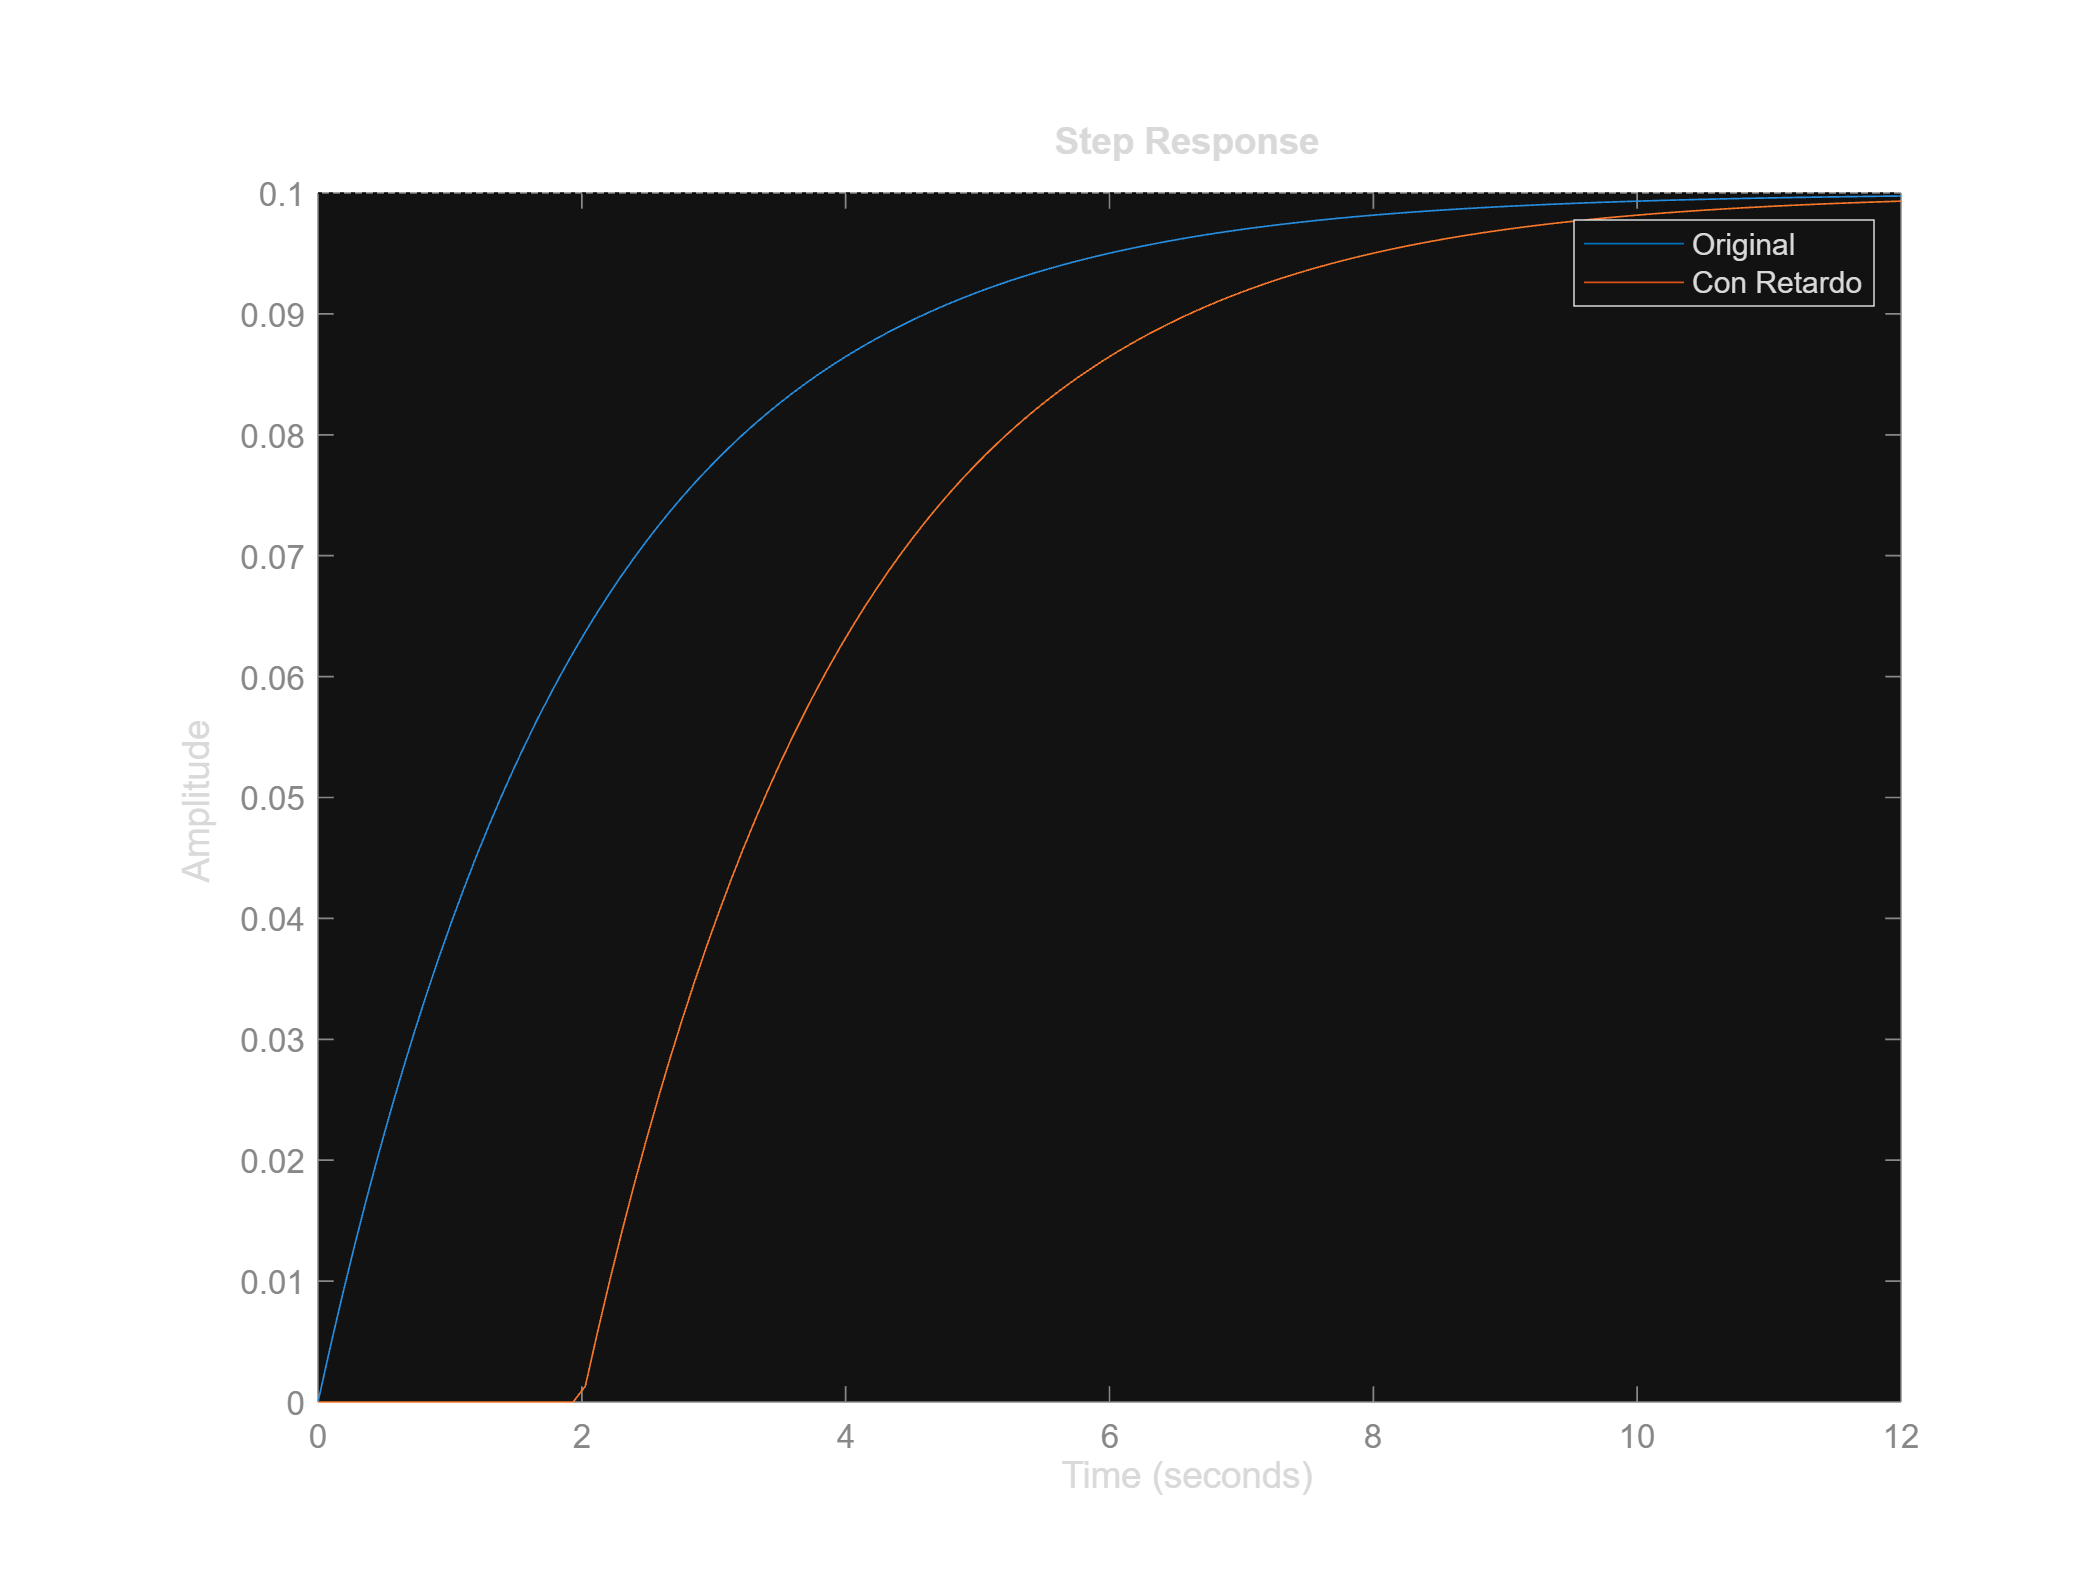

step(0.1*G)
legend('Original','Con Retardo');
hold off;

%AQUÍ ALGÚN ERROR RARO QUE NO ENTIENDO


`Resultado esperado:`

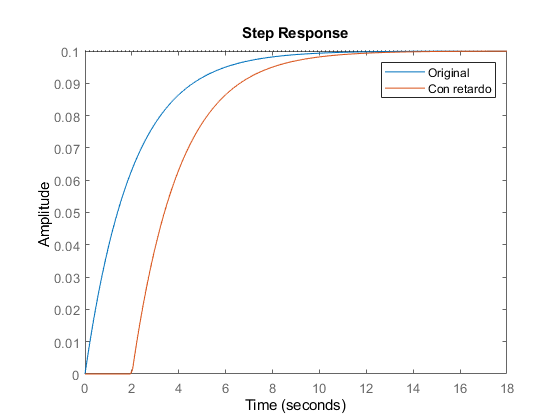

## 2. Aproximación polinomial del retarso

Como hemos visto, la función de transferencia de un tiempo puerto no es racional ($e^{-\lambda s}$). Desde el punto de vista del control, a la hora de aplicar ciertas técnicas como los métodos del lugar de las raíces o de ubicación de polos, es necesario contar con una representación racional formada por ceros y polos. Con este fin se pueden emplear distintas aproximaciones a la definición exacta.

Una de las aproximaciones más empleadas es la de **Padé** que aproxima la exponencial como una división de dos polinomios en términos de la variable compleja $s$. Al tratarse de una aproximación, pueden emplearse términos de distinto orden para realizarla. Cuanto mayor sea el orden de la aproximación, mas cercana estará de la función real, a coste de una mayor complejidad en su cálculo. Por ejemplo, las aproximaciones de primer y segundo orden serían, respectivamente:


$$e^{-\lambda s} \approx \frac{1-\frac{\lambda }{2}s}{1+\frac{\lambda }{2}s}$$



$$e^{-\lambda s} \approx \frac{1-\frac{\lambda }{2}s+\frac{\lambda^2 }{12}s^2 }{1+\frac{\lambda }{2}s+\frac{\lambda^2 }{12}s^2 }$$


Por supuesto, MATLAB dispone de un comando `pade()` para realizar la aproximación del retardo de transporte. En concreto, su sintaxis es.

- `sysx=pade(sys, d)` que devuelve en `sysx` la aproximación de Padé de orden `d` del sistema `sys`. 

El siguiente código muestra un ejemplo del uso de este comando con aproximaciones de distinto orden, y compara la respuesta del sistema con el retraso exacto y con el retraso aproximado.

d =5% Orden de la aproximación de Padé

d = 5

s=tf('s');               % Creación de la función de transferencia básica
sys=exp(-lambda*s);      % Función de retardo 
sysx=pade(sys,d)         % Aproximación de Padé por MATLAB

sysx =
 
  -s^5 + 15 s^4 - 105 s^3 + 420 s^2 - 945 s + 945
  -----------------------------------------------
  s^5 + 15 s^4 + 105 s^3 + 420 s^2 + 945 s + 945
 
Continuous-time transfer function.
Model Properties


G_approx=sysx*tf(2,[1,1])      % Función de transferencia con el retraso incorporado

G_approx =
 
     -2 s^5 + 30 s^4 - 210 s^3 + 840 s^2 - 1890 s + 1890
  ----------------------------------------------------------
  s^6 + 16 s^5 + 120 s^4 + 525 s^3 + 1365 s^2 + 1890 s + 945
 
Continuous-time transfer function.
Model Properties


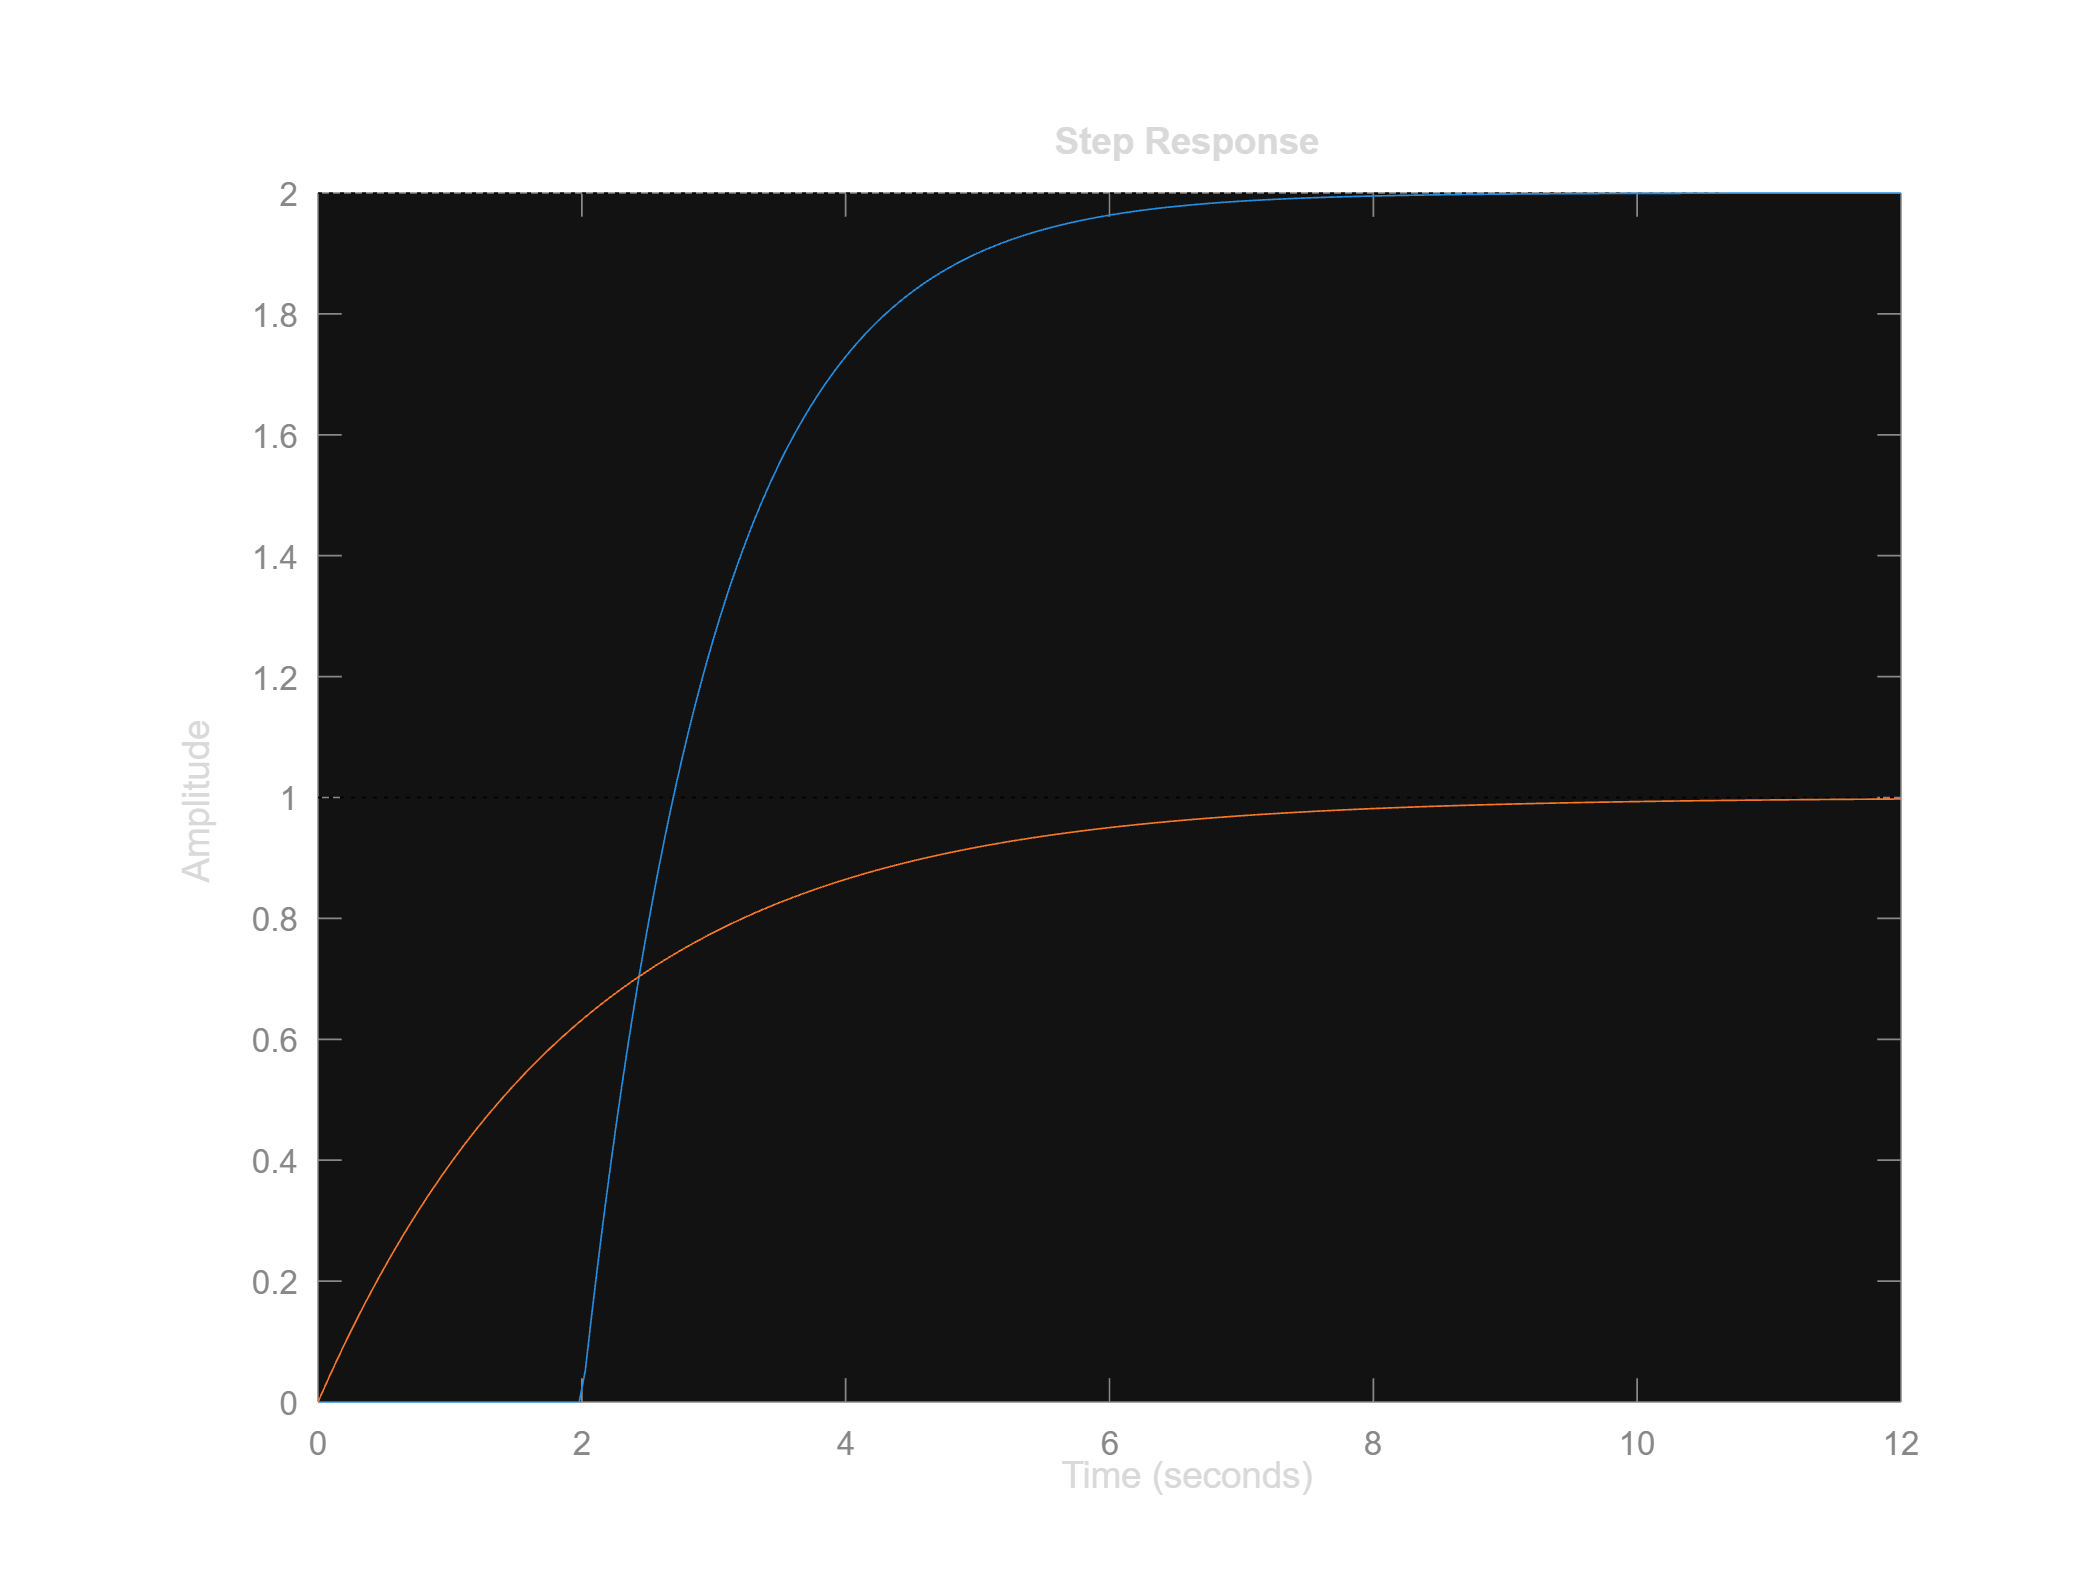

G = tf(2,[1 1],'IODelay',lambda) ;
step(G,G1);              % Comparación de la aproximación G1con la función G de refrencia

**¡OJO!** Si nos fijamos, la aproximación de Padé introduce un cero en el semiplano derecho del plano-$s$, por lo que la respuesta escalón del sistema aproximado puede presentar un sobrepaso negativo cerca de $t=0$.

**Tarea 2:** Repite la simulación realizada en la Tarea 1, pero añadiendo un nuevo sistema en el que el retraso se modele empleando una aproximación de Padé de segundo orden.

% Tu código aquí
s = tf('s');
A = 0.1;
R = 1;
C = 2; 
G1 = ((R)/(R*C*s+1));
step(0.1*G1);
hold on;
s = tf('s');
lambda = 2;
Gr = exp(-lambda*s);
Gp = ((R)/(R*C*s+1));
G = Gr*Gp

G =
 
                 1
  exp(-2*s) * -------
              2 s + 1
 
Continuous-time transfer function.
Model Properties


step(0.1*G);

s=tf('s');               % Creación de la función de transferencia básica
sys=exp(-lambda*s);      % Función de retardo 
sysx=pade(sys,2)         % Aproximación de Padé por MATLAB

sysx =
 
  s^2 - 3 s + 3
  -------------
  s^2 + 3 s + 3
 
Continuous-time transfer function.
Model Properties


G_approx = (sysx*G)

G_approx =
 
                   s^2 - 3 s + 3
  exp(-2*s) * -----------------------
              2 s^3 + 7 s^2 + 9 s + 3
 
Continuous-time transfer function.
Model Properties


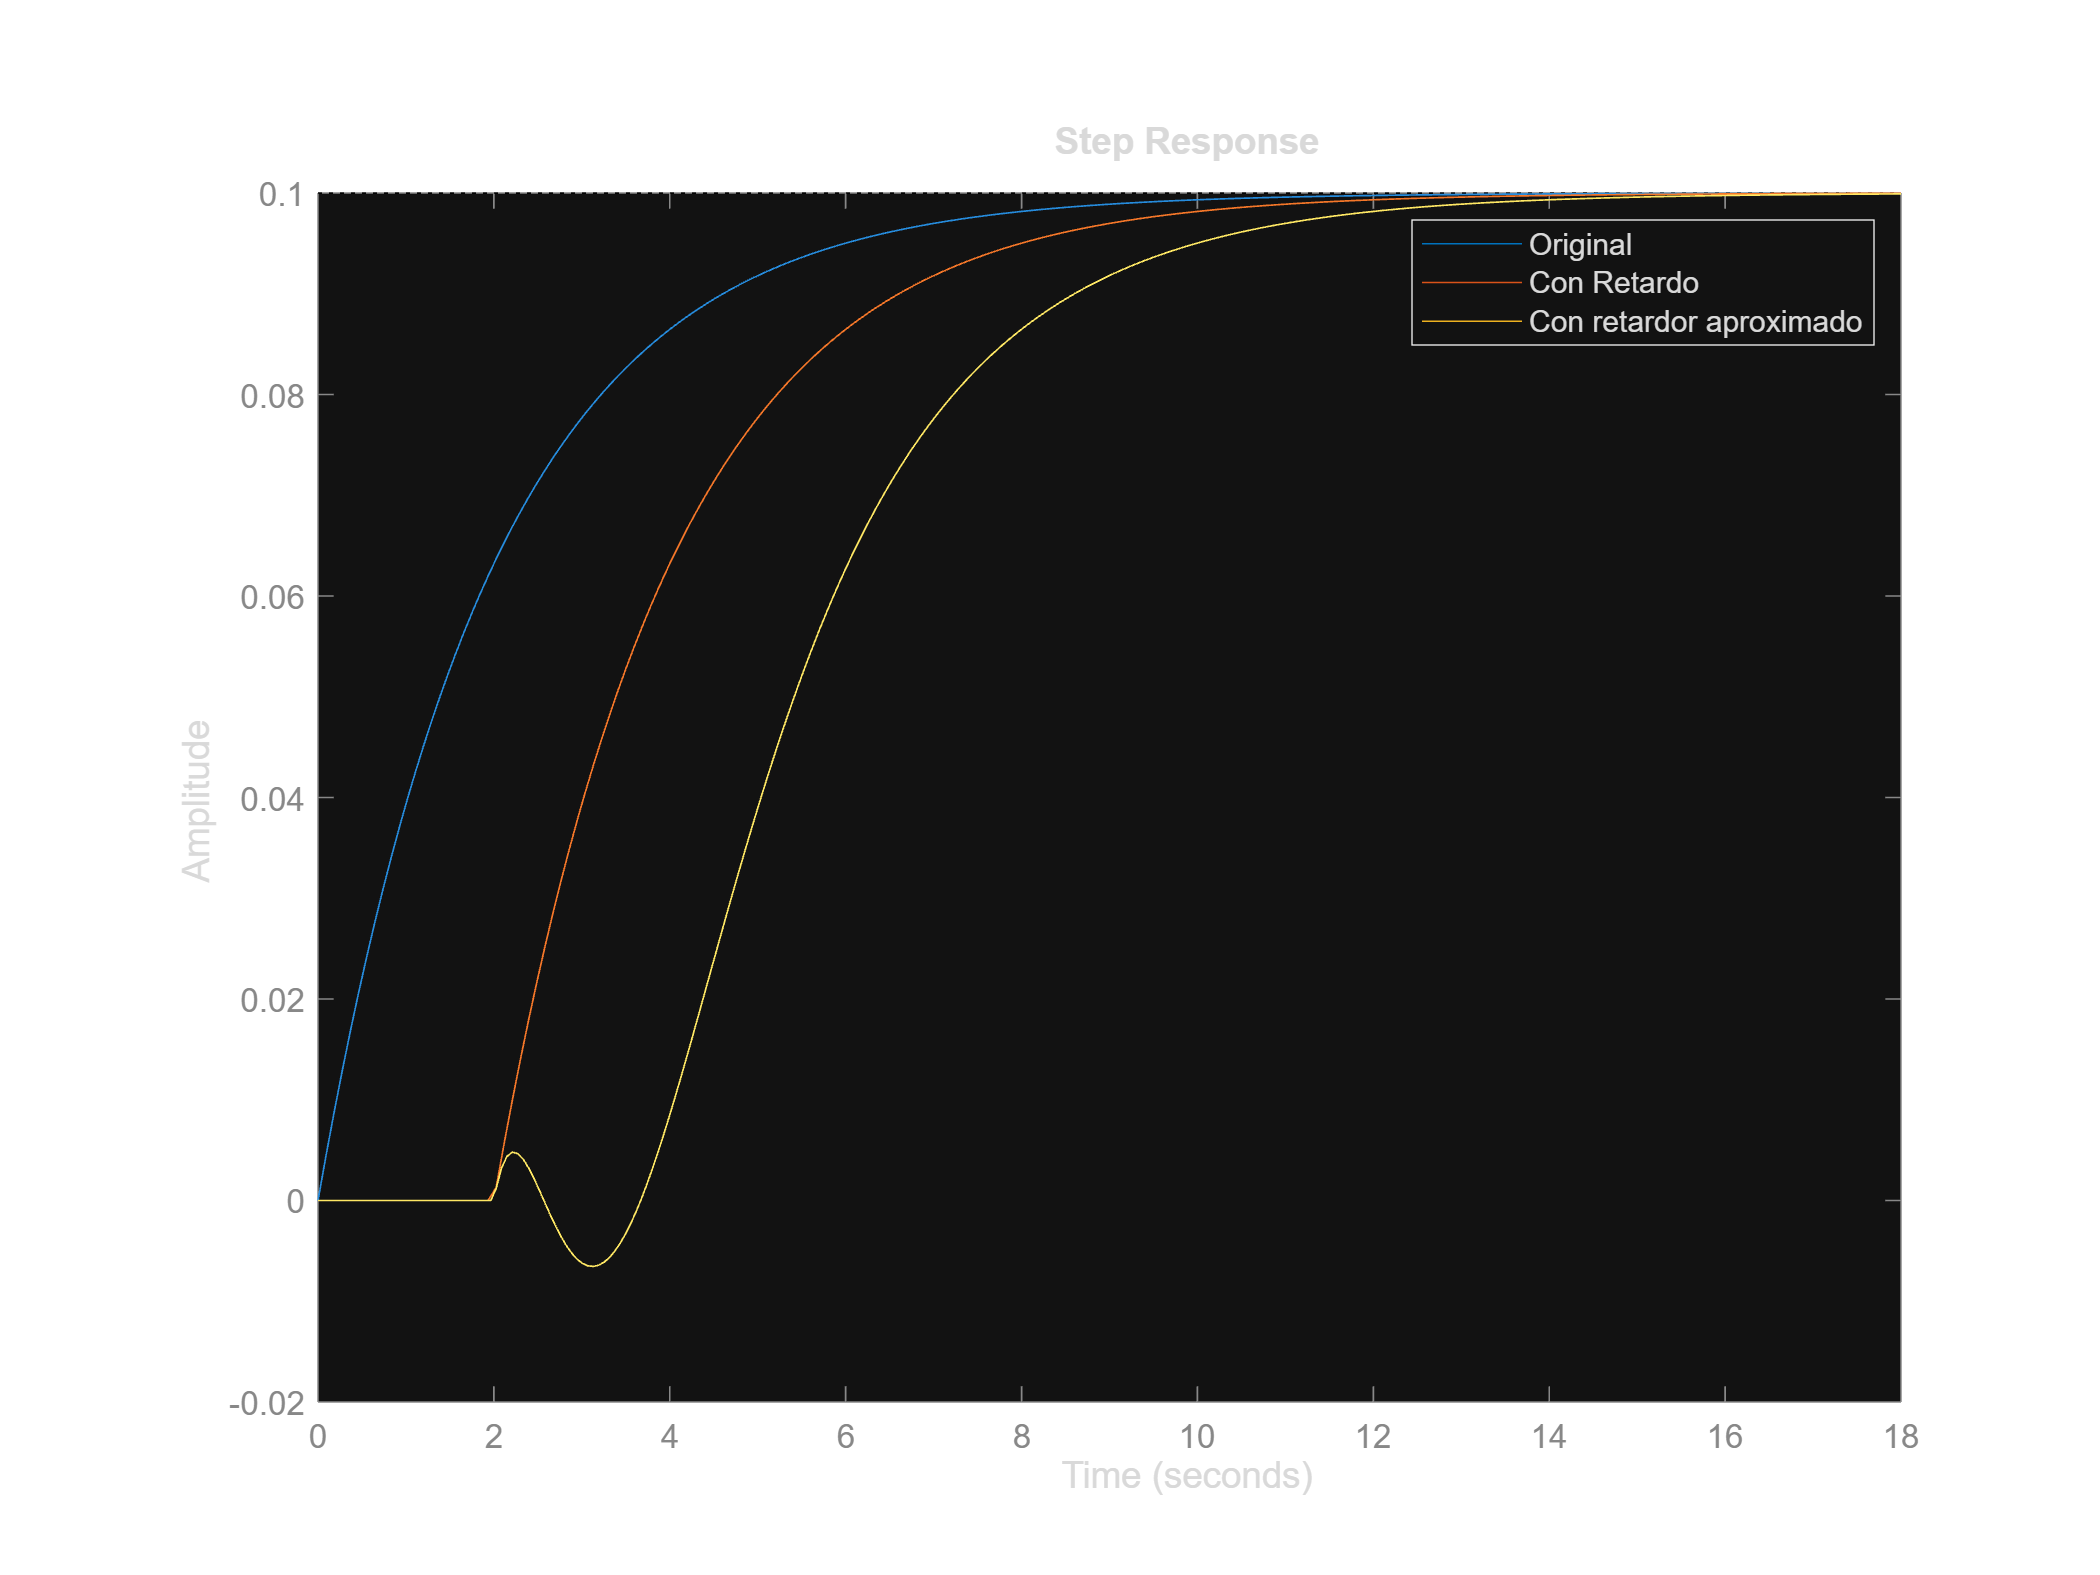

step(0.1*G_approx)
legend('Original','Con Retardo','Con retardor aproximado');
hold off;

%NO SE COMO MOVER ESTO A SU POSICIÓN CORRECTA HE PROBADO -2 A LA FUNCIÓN DE
%APROXIMACION PERO NO HE CONSEGUIDO QUE SE MUEVA COMO QUIERO

`Resultado esperado:`